Four LTI system descriptions

-difference equation (used for computation)

-impulse response (computation + intuition)

-frequency response (intuition)

-system function (intuition) = transfer function * z^n

Four Characteristics

-Causal

-Time-invariant

-Linear

-BIBO stable

## Filters

close all
clear

## System Functions

% Low-Pass Filter lets low freq pass
ALP= [1,-2,1];
BLP= [1,zeros(1,5),-2,zeros(1,5),1];

% High-Pass Filter lets high freq pass
AHP = [1, 1];
BHP = [-1,zeros(1,15),32,zeros(1,15),1];

% Derivative
%AD = [1];
%BD = (1/8)*[]

## Filter with EKG signal

%chain theses?

%LP = filter(BLP,ALP,EKG signal);
%HP = filter(BHP,AHP,EKG signal);

## Roots of the Characteristic Equation

%'Low Pass characteristic equation roots'
root_1 = roots(ALP)

root_1 =      1
     1


for i = root_1
    abs(i)
end

ans =      1
     1



%'High Pass characteristic equation roots'
root_2 = roots(AHP)

root_2 = -1

for i = root_2
    abs(i)
end

ans = 1

## Impulse Responses

imp = [1, zeros(1,99)]; 
% impulse = perturbation
% recall that the impulse response of an LTI system is the output
% of the system whne an impulse is applied to a system a rest

%h1 = filter(BLP,ALP,imp);
%h2 = filter(BHP,AHP,imp);

## Frequency Response

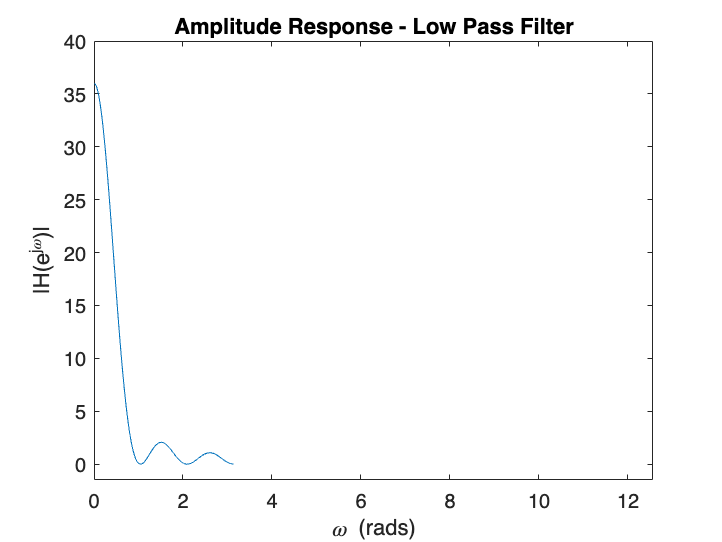

% response of a system to a complex sinusoid only LTI
%[h,w] = freqz(b,a,n) returns the n-point frequency response vector h 
% and the corresponding angular frequency vector w for the digital 
% filter with transfer function coefficients stored in b and a.

%low pass
[HLP,WLP] = freqz(BLP,ALP);
figure
plot(WLP,abs(HLP));
ylim([-1.5,40])
xlim([0,4*pi])
title('Amplitude Response - Low Pass Filter')
xlabel('\omega (rads)')
ylabel('|H(e^{j\omega})|')

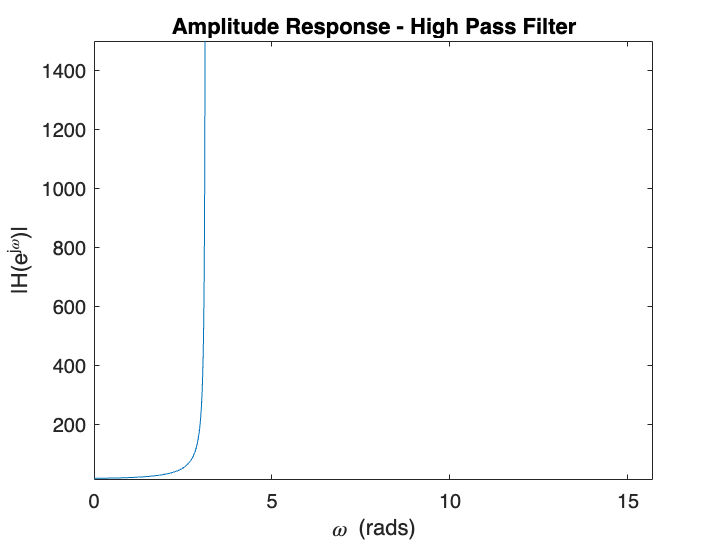


%high pass
[HHP,WHP] = freqz(BHP,AHP);
figure
plot(WHP,abs(HHP));
ylim([10,1500])
xlim([0,5*pi])
title('Amplitude Response - High Pass Filter')
xlabel('\omega (rads)')
ylabel('|H(e^{j\omega})|')


%derivative
% [HD,WD] = freqz(BD,AD);
% figure
% plot(WD,abs(HD));
% ylim([10,1500])
% xlim([0,5*pi])
% title('Amplitude Response - Derivative')
% xlabel('\omega (rads)')
% ylabel('|H(e^{j\omega})|')

## Output for Low and High Frequency Cosine Inputs

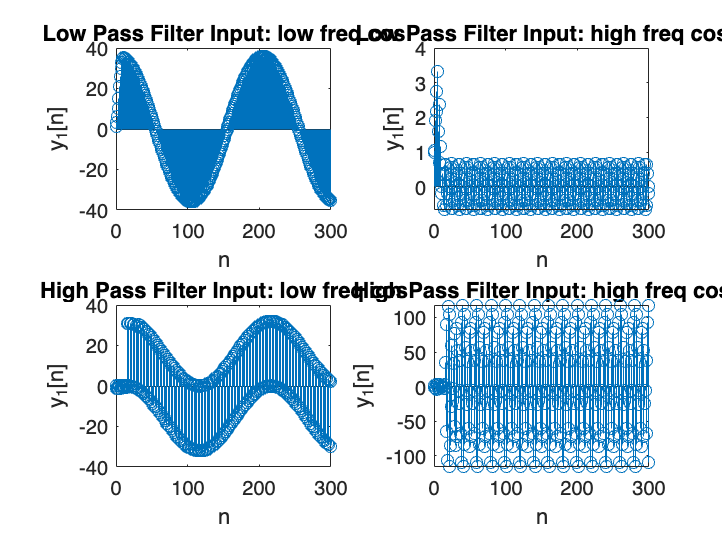

f_low = 1;
f_high = 90;
fs = 200;
n = 0:1:300;

lowcos = cos(2*pi*(f_low/fs)*n);
highcos = cos(2*pi*(f_high/fs)*n);

cl1 = filter(BLP,ALP,lowcos);
ch1 = filter(BLP,ALP,highcos);

cl2 = filter(BHP,AHP,lowcos);
ch2 = filter(BHP,AHP,highcos);

subplot(2,2,1)
stem(n,cl1)
xlabel('n')
ylabel('y_1[n]')
title('Low Pass Filter Input: low freq cos')

subplot(2,2,2)
stem(n,ch1)
xlabel('n')
ylabel('y_1[n]')
title('Low Pass Filter Input: high freq cos')

subplot(2,2,3)
stem(n,cl2)
xlabel('n')
ylabel('y_1[n]')
title('High Pass Filter Input: low freq cos')

subplot(2,2,4)
stem(n,ch2)
xlabel('n')
ylabel('y_1[n]')
title('High Pass Filter Input: high freq cos')